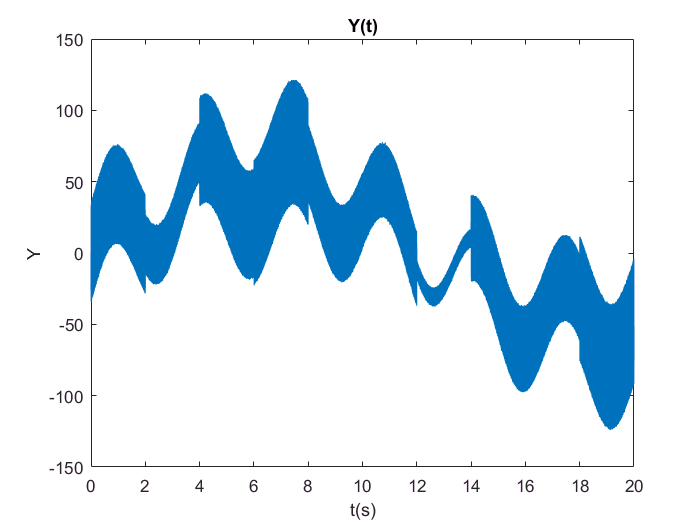

clear
%% 1
Y = HW1_sig(810198479);
t = 0:20*1/length(Y):20-20*1/length(Y);

plot(t,Y);
xlabel('t(s)')
ylabel('Y')
title('Y(t)')

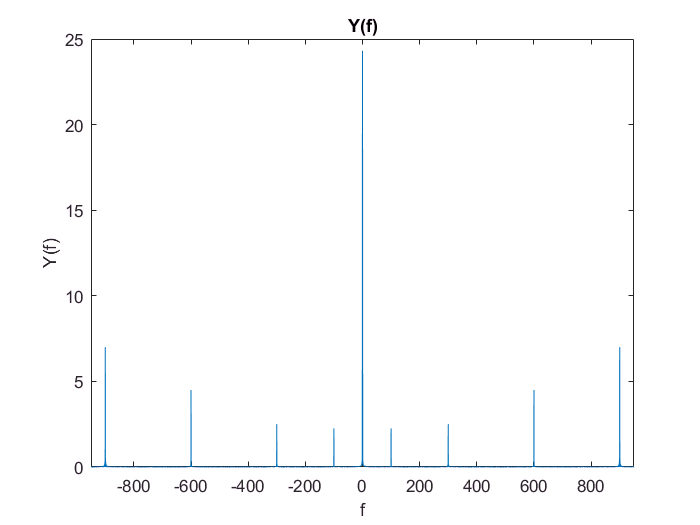


fs=100000;
f=-fs/2:fs/length(Y):fs/2-fs/length(Y);

Yf = abs(fftshift(fft(Y))/length(Y));
figure
plot(f,Yf);
xlim([-950 950]);
xlabel('f')
ylabel('Y(f)')
title('Y(f)')

%% 2
fl = 5;
Rc = 1/(2*pi*fl);
g = tf(1,[Rc 1])


g =
 
        1
  -------------
  0.03183 s + 1
 
Continuous-time transfer function.



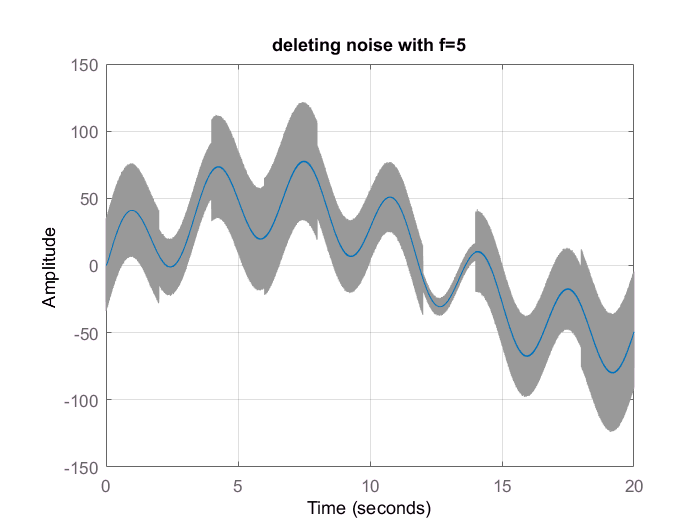

lsim(g,Y,t)
grid on
title('deleting noise with f=5')

%% 3
fl = 100;
Rc = 1/(2*pi*fl);
g = tf(1,[Rc 1])


g =
 
        1
  --------------
  0.001592 s + 1
 
Continuous-time transfer function.



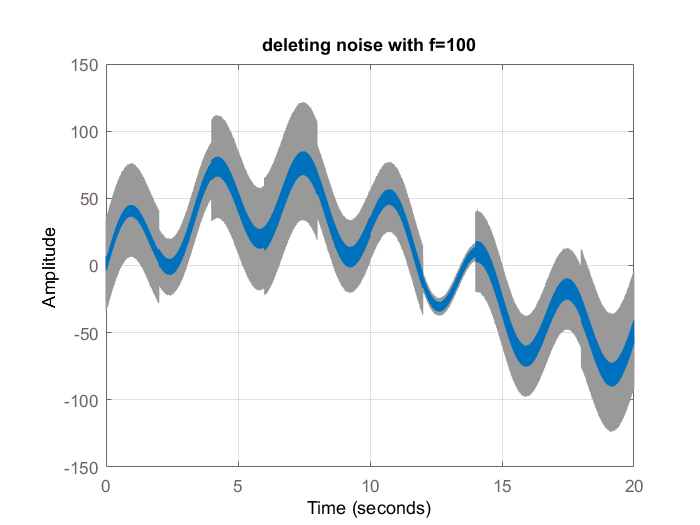

lsim(g,Y,t)
grid on
title('deleting noise with f=100')



fl = 300;
Rc = 1/(2*pi*fl);
g = tf(1,[Rc 1])


g =
 
         1
  ---------------
  0.0005305 s + 1
 
Continuous-time transfer function.



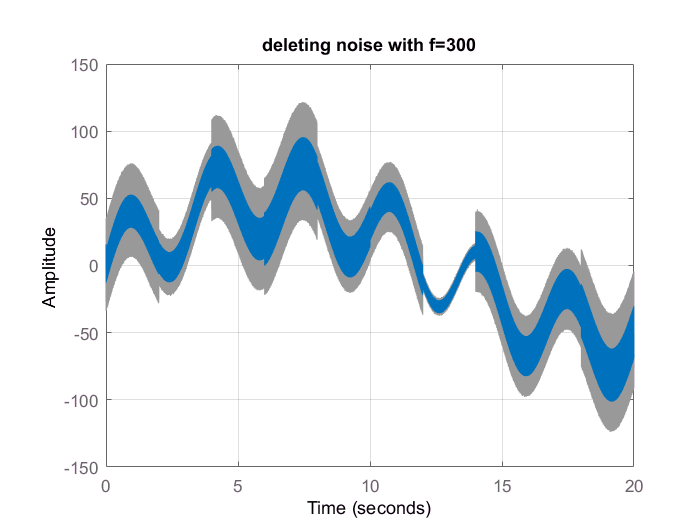

lsim(g,Y,t)
grid on
title('deleting noise with f=300')

%% 4 %% f = 100
fc = 100;
RhCh1 = 1/(fc - 10);
RlCl1 = 1/(fc + 10);
g100 = tf([RhCh1 0],[RhCh1*RlCl1 RhCh1+RlCl1 1])


g100 =
 
           0.01111 s
  ---------------------------
  0.000101 s^2 + 0.0202 s + 1
 
Continuous-time transfer function.



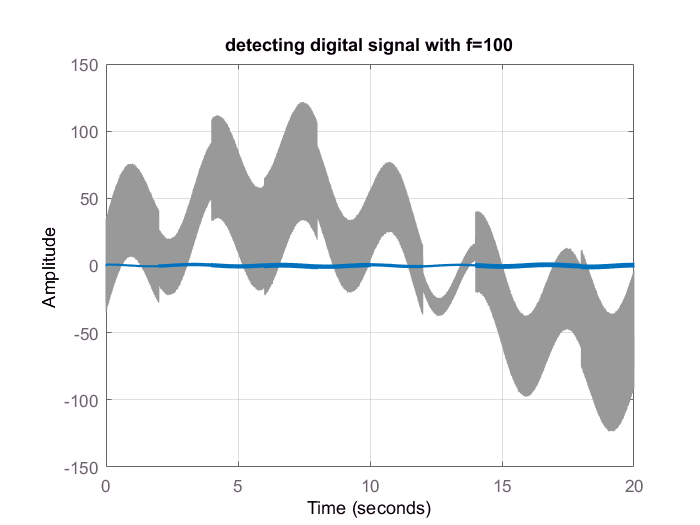

lsim(g100,Y,t)
grid on
title('detecting digital signal with f=100')

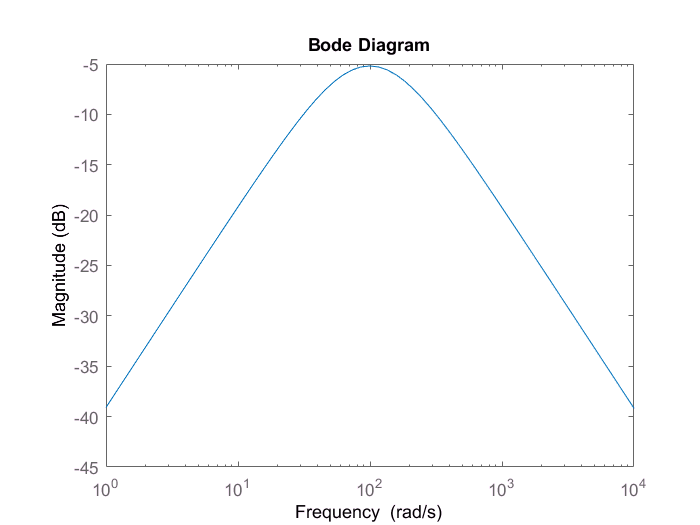


%% 5 %% f = 100
bodemag(g100)


k =1/10^(-5.19/20);
kg100 = k*g100


kg100 =
 
           0.0202 s
  ---------------------------
  0.000101 s^2 + 0.0202 s + 1
 
Continuous-time transfer function.



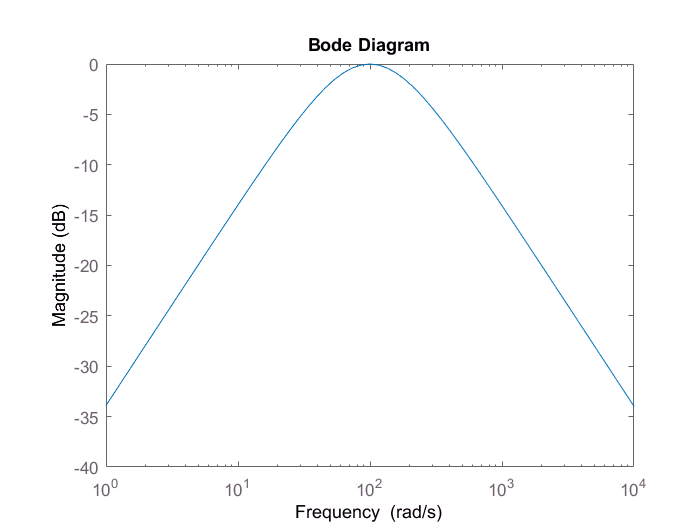

bodemag(kg100)

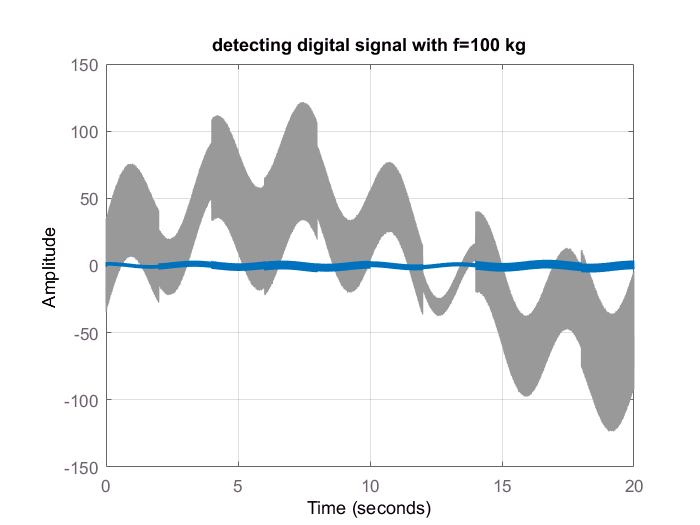

lsim(kg100,Y,t)
grid on
title('detecting digital signal with f=100 kg')

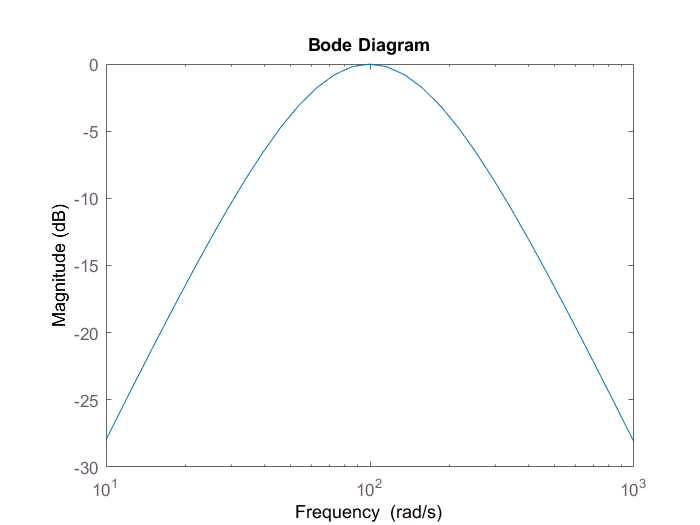


%% 6 %% f = 100
n = 2;
F100 = (kg100)^n;
bodemag(F100)

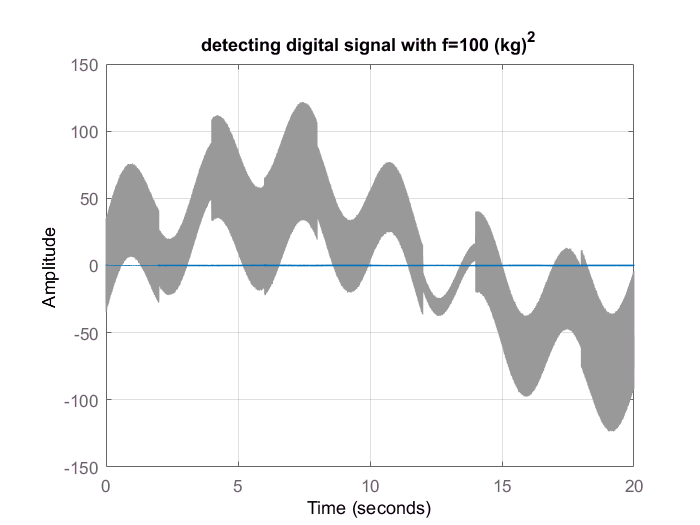

lsim(F100,Y,t)
grid on
title('detecting digital signal with f=100 (kg)^2')

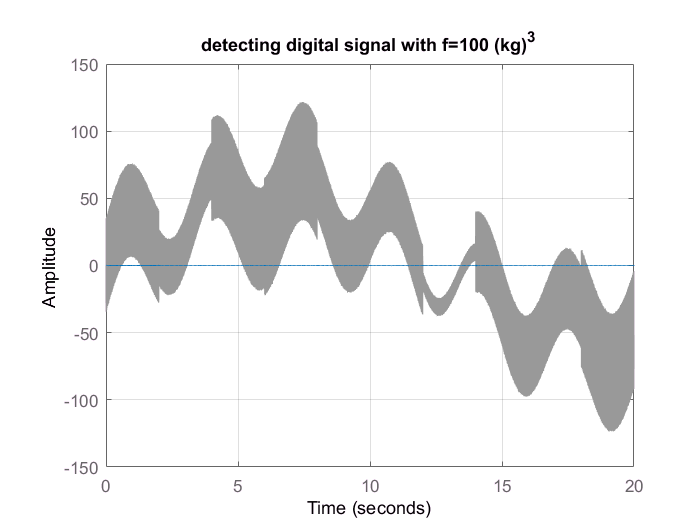

n = 3;
F100 = (kg100)^n;

lsim(F100,Y,t)
grid on
title('detecting digital signal with f=100 (kg)^3')

%% 4 %% f = 300
fc2 = 300;
RhCh2 = 1/(fc2 - 10);
RlCl2 = 1/(fc2 + 10);
g300 = tf([RhCh2 0],[RhCh2*RlCl2 RhCh2+RlCl2 1])


g300 =
 
            0.003448 s
  ------------------------------
  1.112e-05 s^2 + 0.006674 s + 1
 
Continuous-time transfer function.



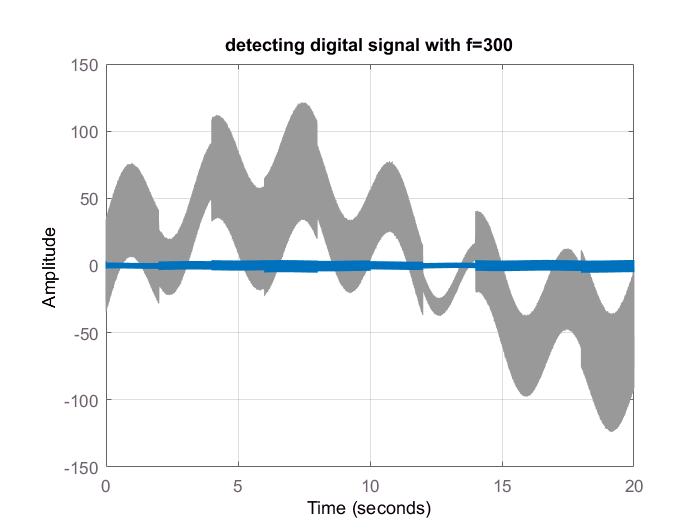

lsim(g300,Y,t)
grid on
title('detecting digital signal with f=300')

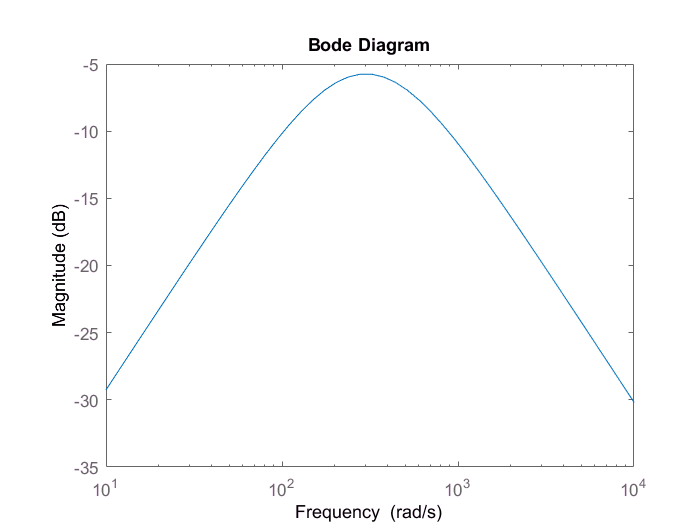


%% 5 %% f = 300
bodemag(g300)


k =1/10^(-5.76/20);
kg300 = k*g300


kg300 =
 
            0.006693 s
  ------------------------------
  1.112e-05 s^2 + 0.006674 s + 1
 
Continuous-time transfer function.



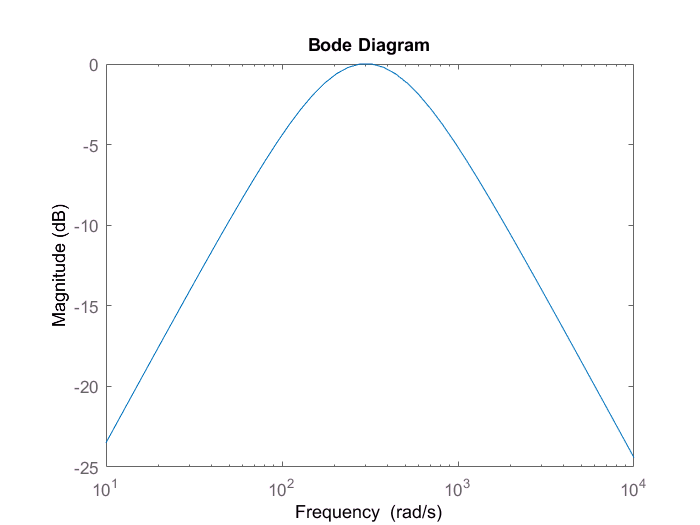

bodemag(kg300)

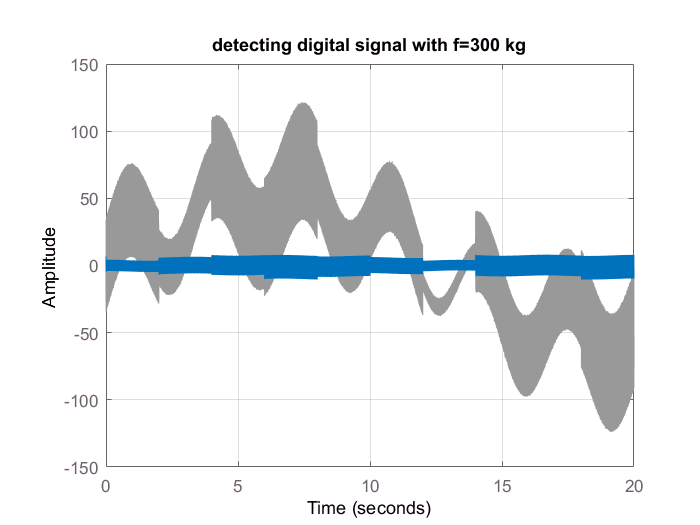

lsim(kg300,Y,t)
grid on
title('detecting digital signal with f=300 kg')

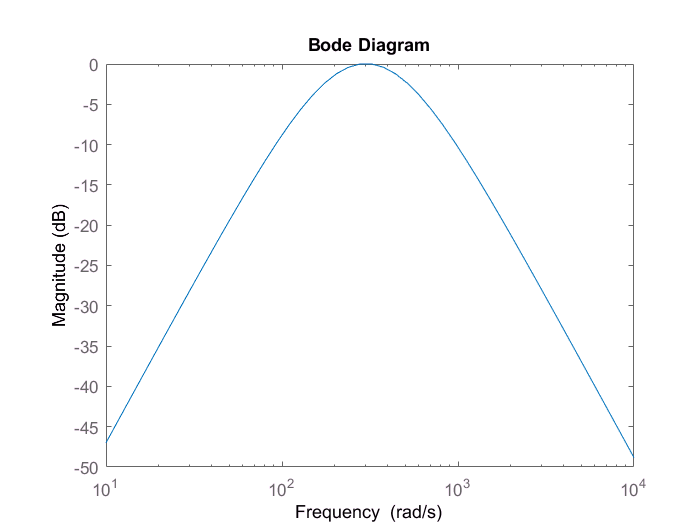


%% 6 %% f = 300
n = 2;
F300 = (kg300)^n;
bodemag(F300)

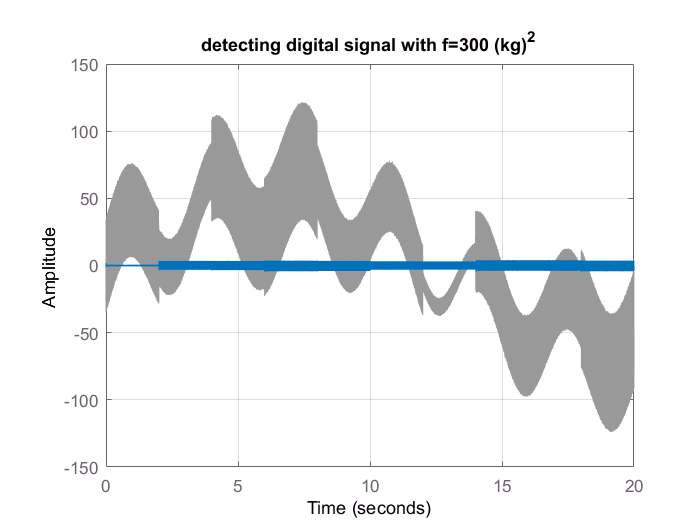

lsim(F300,Y,t)
grid on
title('detecting digital signal with f=300 (kg)^2')

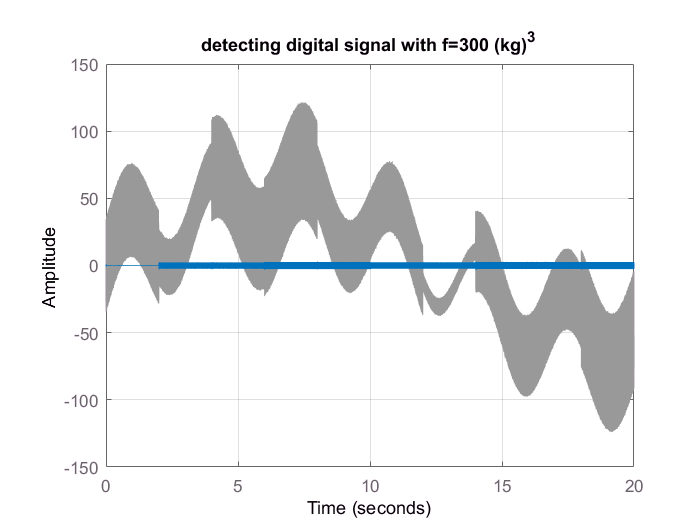

n = 3;
F300 = (kg300)^n;

lsim(F300,Y,t)
grid on
title('detecting digital signal with f=300 (kg)^3')

%% 4 %% f = 600
fc = 600;
RhCh3 = 1/(fc - 10);
RlCl3 = 1/(fc + 10);
g600 = tf([RhCh3 0],[RhCh3*RlCl3 RhCh3+RlCl3 1])


g600 =
 
            0.001695 s
  ------------------------------
  2.779e-06 s^2 + 0.003334 s + 1
 
Continuous-time transfer function.



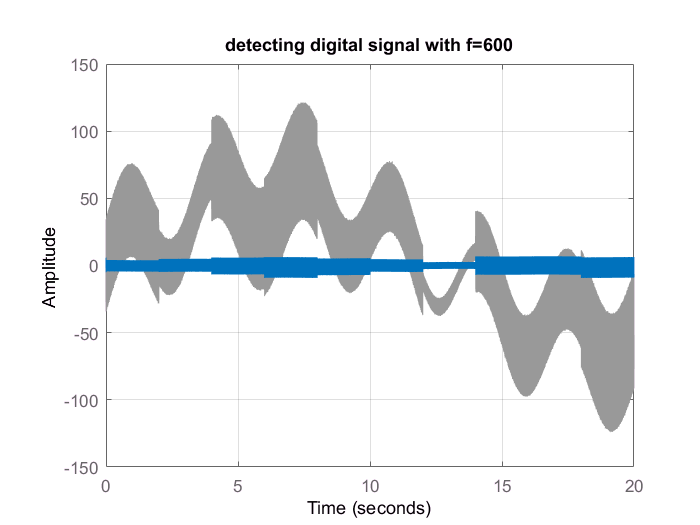

lsim(g600,Y,t)
grid on
title('detecting digital signal with f=600')

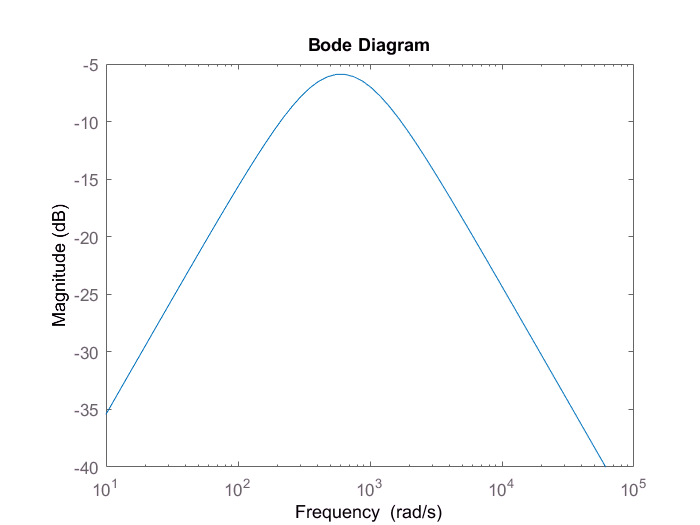


%% 5 %% f = 600
bodemag(g600)


k =1/10^(-5.9/20);
kg600 = k*g600


kg600 =
 
            0.003343 s
  ------------------------------
  2.779e-06 s^2 + 0.003334 s + 1
 
Continuous-time transfer function.



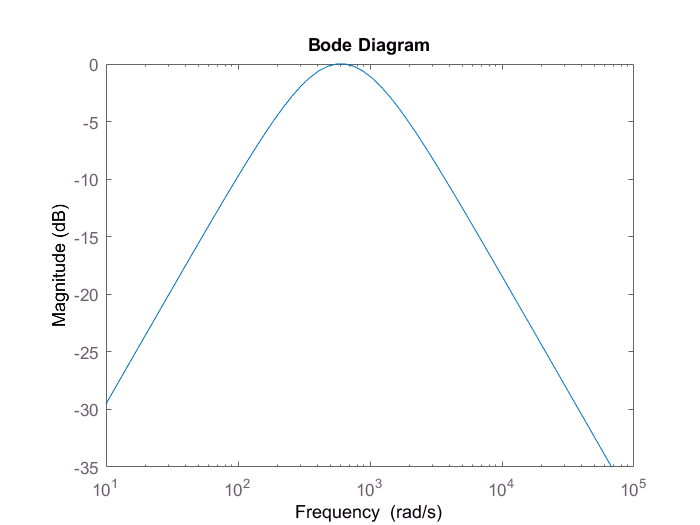

bodemag(kg600)

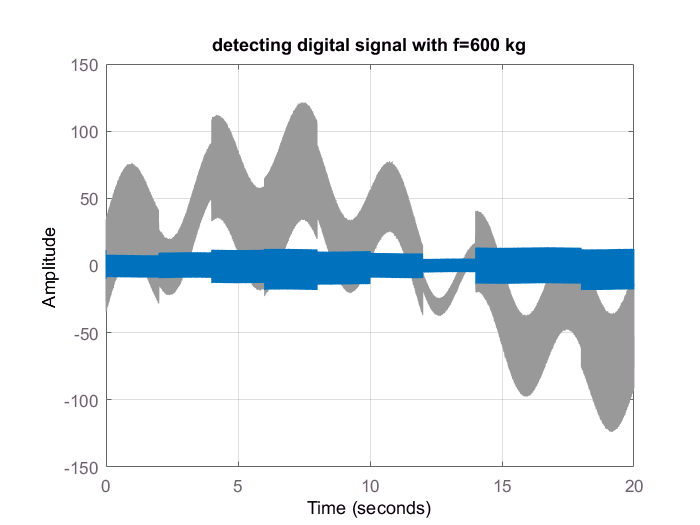

lsim(kg600,Y,t)
grid on
title('detecting digital signal with f=600 kg')

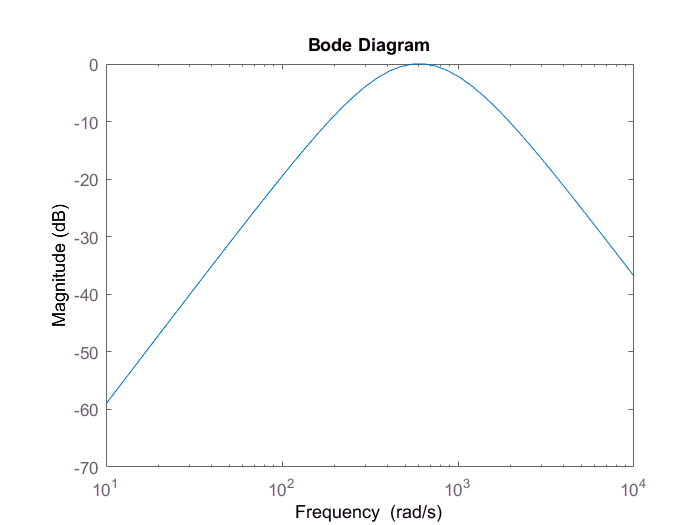


%% 6 %% f = 600
n = 2;
F600 = (kg600)^n;
bodemag(F600)

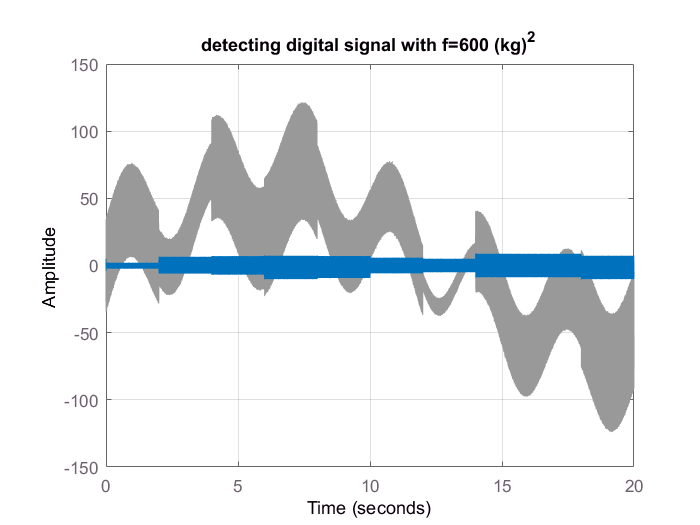

lsim(F600,Y,t)
grid on
title('detecting digital signal with f=600 (kg)^2')

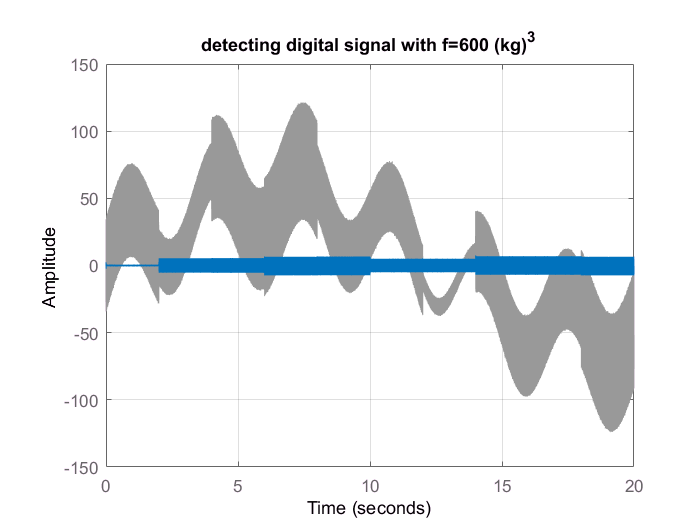

n = 3;
F600 = (kg600)^n;

lsim(F600,Y,t)
grid on
title('detecting digital signal with f=600 (kg)^3')

%% 4 %% f = 900
fc = 900;
RhCh4 = 1/(fc - 10);
RlCl4 = 1/(fc + 10);
g900 = tf([RhCh4 0],[RhCh4*RlCl4 RhCh4+RlCl4 1])


g900 =
 
            0.001124 s
  ------------------------------
  1.235e-06 s^2 + 0.002222 s + 1
 
Continuous-time transfer function.



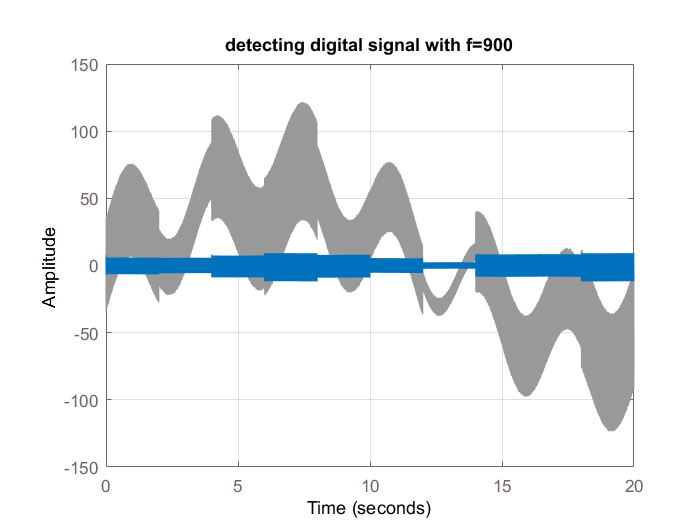

lsim(g900,Y,t)
grid on
title('detecting digital signal with f=900')

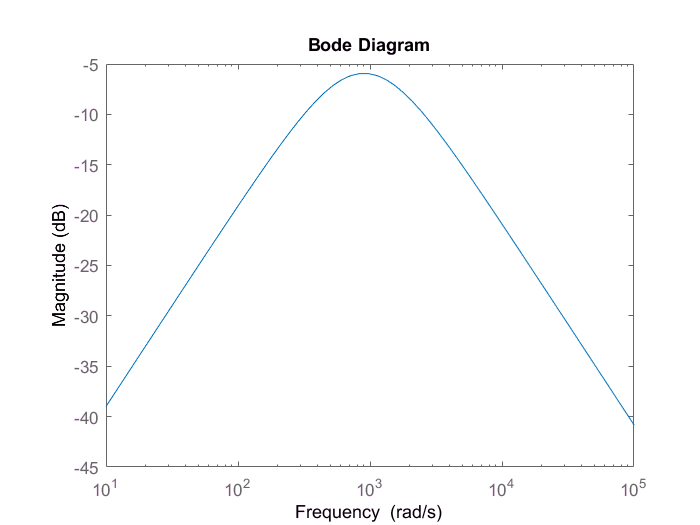


%% 5 %% f = 900
bodemag(g900)


k =1/10^(-5.19/20);
kg900 = k*g900


kg900 =
 
            0.002042 s
  ------------------------------
  1.235e-06 s^2 + 0.002222 s + 1
 
Continuous-time transfer function.



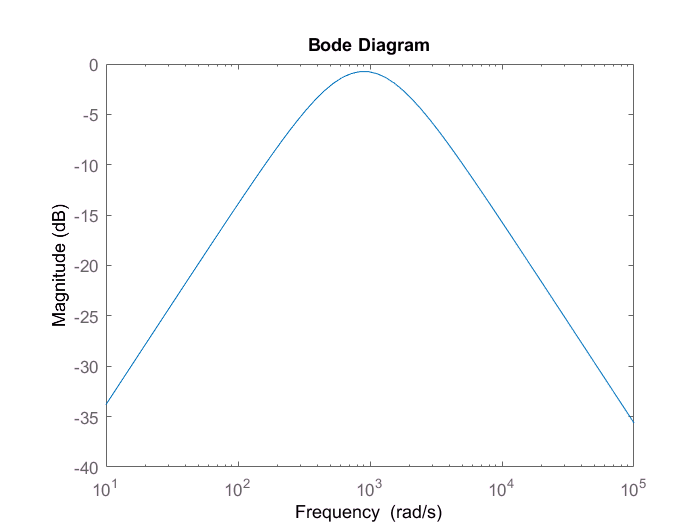

bodemag(kg900)

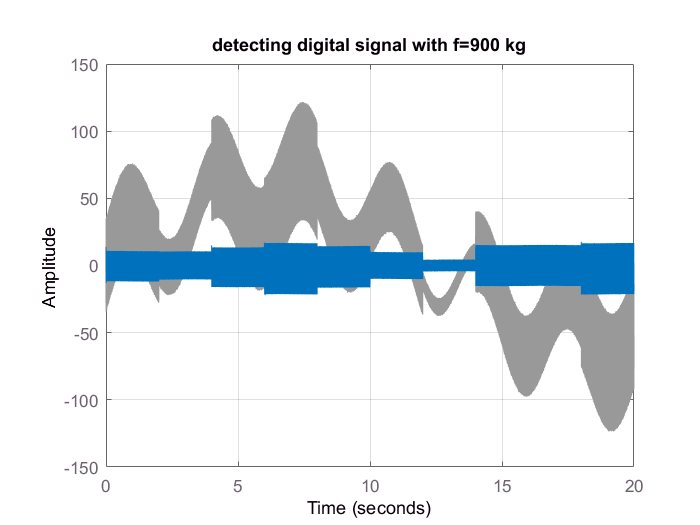

lsim(kg900,Y,t)
grid on
title('detecting digital signal with f=900 kg')

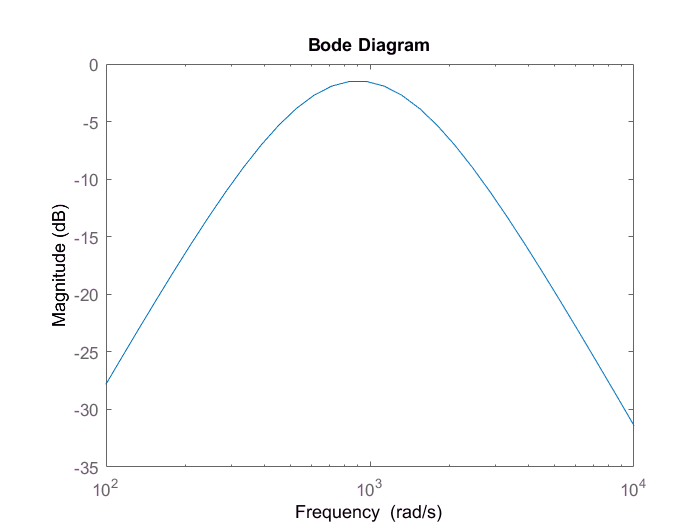


%% 6 %% f = 900
n = 2;
F900 = (kg900)^n;
bodemag(F900)

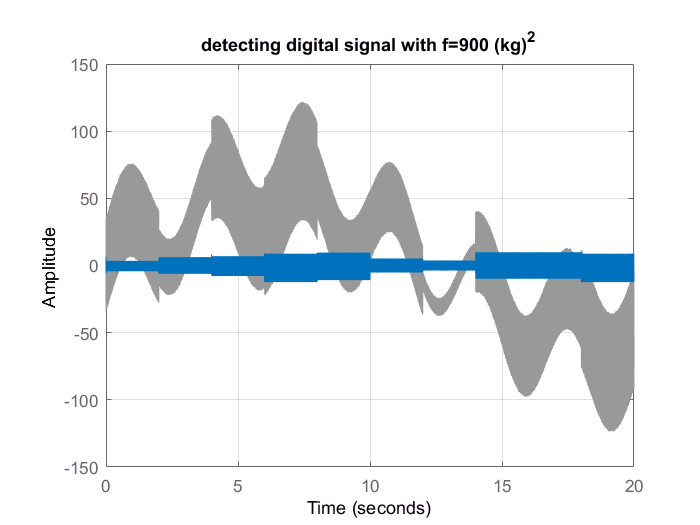

lsim(F900,Y,t)
grid on
title('detecting digital signal with f=900 (kg)^2')

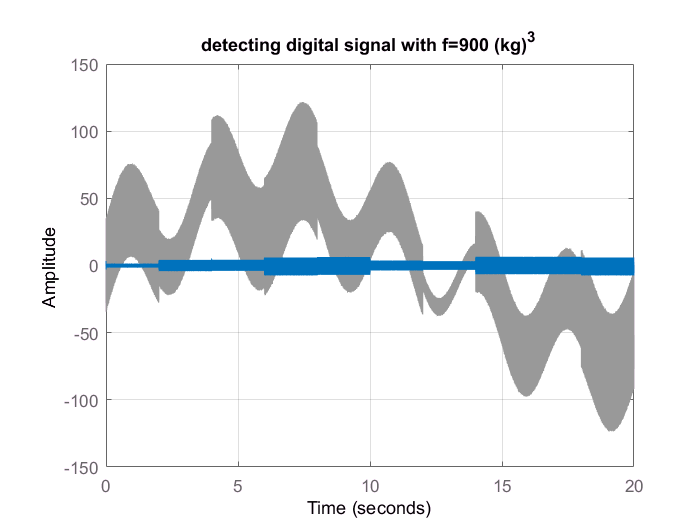

n = 3;
F900 = (kg900)^n;

lsim(F900,Y,t)
grid on
title('detecting digital signal with f=900 (kg)^3')

%%% 10

fl = 900;
Rc = 1/(2*pi*fl);
g = tf([Rc 0],[Rc 1])


g =
 
    0.0001768 s
  ---------------
  0.0001768 s + 1
 
Continuous-time transfer function.



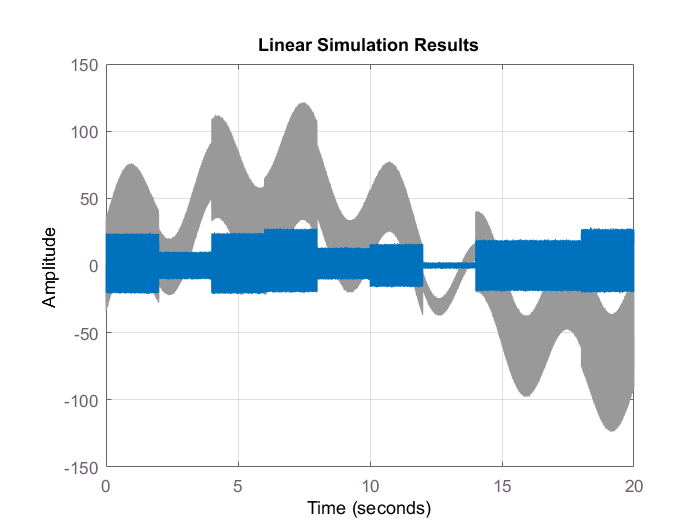

lsim(g,Y,t)
grid on